# Principal Moments of Inertia

In this task we're going to look at how we can calculate the principal axes and principal moments of inertia, of a rigid body.  Recall our well known angular momentum equation $\bf ^BL = {^BI} \times {^B\omega}$, where the *B-frame* about which we are determining the angular momentum is both BODY fixed AND at the body's centre of mass:

        $\pmatrix{^BL_{X} \cr ^BL_{\thinspace Y} \cr ^BL_{\thinspace  Z}} = 
\pmatrix{
^BI_{XX} & ^BI_{XY} & ^BI_{XZ} \cr
^BI_{XY} & ^BI_{YY} & ^BI_{YZ} \cr
^BI_{XZ} & ^BI_{YZ} & ^BI_{ZZ} \cr
} *
\pmatrix{^B_G\omega_X \cr 
^B_G\omega_Y \cr 
^B_G\omega_Z \cr 
}$      where      $\matrix{ 
^BI_{ZZ} = \int (X^2 + Y^2)  dm \cr
^BI_{XY} = \int(-X *Y)  dm 
}$       etc.

What we would like to do is to determine another co-ordinate frame, call it the *P-frame*, which is also at the body's centre of mass, but the inertia matrix about this new *P-frame* is diagonal.  We call this *P-frame* the **PRINCIPAL** frame and the corresponding diagonal inertia matrix the **PRINCIPAL **moment of inertia matrix $^PI$, ie:


$$^PL = {^PI} \times {^P\omega} \qquad where \qquad {^PI} = \pmatrix{
I_1 & 0 & 0 \cr
0 & I_2 & 0 \cr
0 & 0 & I_3 \cr
} $$


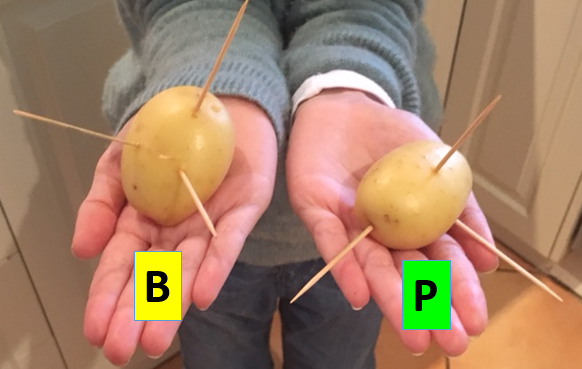

## What we're going to do:

Key topics that we'll cover in this task are:

- review Eigenvalues for a general matrix

- review Eigenvalues for a **SYMMETRIC** matrix

- review passive rotations and the DCM

After reviewing these topics we'll present the solution to determining the **PRINCIPAL** moments of inertia.

`Bradley Horton : 01-Mar-2016, bradley.horton@mathworks.com.au`

## ATTENTION:  before we start I want the following acknowledged:

*In the MATLAB doc for the *`eig() `*function it states that when you specifically use this calling syntax:*

*        >>  *`[V,D] = eig(A)`*, *

*That the returned eigenvectors *`V`* are normalised such that the 2-norm is 1.  For other calling syntaxes, this normalization scheme is NOT necessarily used. *

*So?  *

*So in this task, we'll be using the above calling syntax which gives us nomalised eigenvectors of magnitude 1 !!*

## Eigenvalue problems

Recall the eigenvalue problem for a square matrix $A \in R^{n \times n}$:


$$A  \times \vec{v} _i = \lambda_i . \vec{v}_i 
$$
  
$$\Longrightarrow$$
  
$$det( A - \lambda_i \thinspace. \thinspace I) = 0$$


syms I_xx I_xy I_xz I_yy I_yz I_zz lambda
% define the original inertia matrix
A  = [I_xx, I_xy, I_xz;
      I_xy, I_yy, I_yz;
      I_xz, I_yz, I_zz ]  

$$A = \left(\begin{array}{ccc} I_{\mathrm{xx}} & I_{\mathrm{xy}} & I_{\mathrm{xz}}\\ I_{\mathrm{xy}} & I_{\mathrm{yy}} & I_{\mathrm{yz}}\\ I_{\mathrm{xz}} & I_{\mathrm{yz}} & I_{\mathrm{zz}} \end{array}\right)$$

Create the eigenvalue problem:  $det( A - \lambda_i \thinspace. \thinspace I) = 0$

% create the eigenvalue problem
e_mat = A - lambda*eye(3)

$$e\_mat = \left(\begin{array}{ccc} I_{\mathrm{xx}}-\lambda & I_{\mathrm{xy}} & I_{\mathrm{xz}}\\ I_{\mathrm{xy}} & I_{\mathrm{yy}}-\lambda & I_{\mathrm{yz}}\\ I_{\mathrm{xz}} & I_{\mathrm{yz}} & I_{\mathrm{zz}}-\lambda \end{array}\right)$$

det_e = det(e_mat);
det_e = collect(det_e)

$$det\_e = -\lambda^{3}+\left(I_{\mathrm{xx}}+I_{\mathrm{yy}}+I_{\mathrm{zz}}\right)\,\lambda^{2}+\left({I_{\mathrm{xy}}}^{2}+{I_{\mathrm{xz}}}^{2}+{I_{\mathrm{yz}}}^{2}-I_{\mathrm{xx}}\,I_{\mathrm{yy}}-I_{\mathrm{xx}}\,I_{\mathrm{zz}}-I_{\mathrm{yy}}\,I_{\mathrm{zz}}\right)\,\lambda -I_{\mathrm{zz}}\,{I_{\mathrm{xy}}}^{2}+2\,I_{\mathrm{xy}}\,I_{\mathrm{xz}}\,I_{\mathrm{yz}}-I_{\mathrm{yy}}\,{I_{\mathrm{xz}}}^{2}-I_{\mathrm{xx}}\,{I_{\mathrm{yz}}}^{2}+I_{\mathrm{xx}}\,I_{\mathrm{yy}}\,I_{\mathrm{zz}}$$

After determining ALL of the eignvalue ($\lambda_j$) and eigenvector ($\vec{v_j}$) pairs , we can collect them into matrices and write them as a single matrix equation:


$$A \times V =  V \times \Lambda$$
  

where

 
$$V = \pmatrix{ \vec{v}_1 \enspace, \vec{v}_1 \enspace , \vec{v}_3 \enspace , \enspace \ldots \enspace , \vec{v}_n }$$



$$\Lambda = \pmatrix{ 
\lambda_1 & 0  & 0 & 0 \ldots \cr 
0 & \lambda_2 & 0 & 0  \ldots  \cr
0 & 0 & \ddots & 0  \ldots  \cr
0 & 0 & \ldots &  \lambda_n 
}$$


**So you can see that we can covert A into a diaginal matrix using the matrix of A's eigenvectors:**


$$A \times V = V \times \Lambda  $$



$$ \Lambda = V^{-1} \times A \times V$$


Let's have a look at an example using MATLAB's `eig()` function:

% a test matrix
A = [ 1, 2, 3;
      4, 0, 6;
      7, 8, 9];
% compute the eignvectors and eigenvalues  
[V, lambda] = eig(A)  

V =          0.249618525831177         0.834593582174687        0.0333649860902975
         0.419786657256663       -0.0387181374754509        -0.855322133320176
         0.872622343256891        -0.549503829307182         0.517021107843594


lambda =           14.8508964139238                         0                         0
                         0         -1.06800986700038                         0
                         0                         0         -3.78288654692344



% look at how we can diagonalise A:
A_diagonal = inv(V) * A * V

A_diagonal =           14.8508964139238      2.14360008482079e-15      7.97150585611213e-16
     -5.62004642103521e-15         -1.06800986700038      2.63074119731552e-16
     -6.82541111893336e-15      1.87280854560615e-15         -3.78288654692344


## Eigenvalue problems:  When A is Symmetric 

When A is symmetric, ie: $A = A^T$, the eigenvectors corresponding to the distinct eigenvalues have a cool property - the eigenvectors are actually ORTHOGONAL, ie:

                                $\vec{v_j}^T \times \vec{v_k} = 0 $,          for $j \neq k$  and

                                $\vec{v_j}^T \times \vec{v_j} = {| \vec{v_j}} |^2 $,    for $j = k$

If we normalise each of these eigenvectors so that their vector norm is 1 (ie: $\vec{v_j}^T \times \vec{v_j} = 1$), then we say that the eigenvectors are ORTHONORMAL, ie:


$$V \times V^T = I$$



$$V^T = V^{-1}$$


Therefore our diagonalization formula introduced earlier, can now be written as:


$$A \times V = V \times \Lambda  $$



$$ \Lambda = V^{-1} \times A \times V$$



$$ \Lambda = V^{T} \times A \times V$$


Let's look at an example:  

% here is a symmetric matrix A
A = [  1,   -9,  -17;
      -9,    2,   45;
     -17,   45,    3; ];
 
% compute the eignvectors and eigenvalues   
[V, lambda] = eig(A) 

V =          0.135736990480687         0.934088604288597        -0.330233173308538
        -0.684806001514346         0.329332380814612         0.650062245663378
         0.715972212942081          0.13790816612935         0.684372068402605


lambda =          -43.2640844261324                         0                         0
                         0         -4.68300504594354                         0
                         0                         0          53.9470894720759



% look at how we can diagonalise A:
A_should_be_diagonal = V' * A * V

A_should_be_diagonal =          -43.2640844261324     -1.29288227698094e-15     -9.44464824373336e-15
      1.15075743474325e-15         -4.68300504594353      2.20775731283242e-15
     -4.32675952622705e-15      2.40121740226818e-15          53.9470894720759



% demonstrate that V is made up of orthonormal vectors
B_should_be_identity = V * V.'

B_should_be_identity =                          1     -3.48042514704126e-17     -7.51511290066421e-17
     -3.48042514704126e-17                         1      5.24898625206243e-17
     -7.51511290066421e-17      5.24898625206243e-17                         1


OK, so we have 3 mutually orthogonal vectors ... which is awesome, but do these 3 vectors form a Right hand rule trio of vectors?  We can ensure that they do by making the 3rd vector the cross product of the first two, eg:  $V = [\vec{v_1}, \quad \vec{v_2}, \quad (\vec{v_1} \times \vec{v_2})]$

V = bh_we_have_a_RH_frame(V);


 ... yep V gives us a RH rule frame !

V * V.'

ans =                          1     -3.48042514704126e-17     -7.51511290066421e-17
     -3.48042514704126e-17                         1      5.24898625206243e-17
     -7.51511290066421e-17      5.24898625206243e-17                         1


## Principal moments of Inertia:

OK, now for the main event.  Let's look at how we now calculate the principal axes of a rigid body.  Recall our well known angular momentum equation $^BL = {^BI} \times {^B\omega}$ where the frame about which we are determining the angular momentum is both BODY fixed AND at the body's centre of mass:

        $\pmatrix{^BL_{X} \cr ^BL_{\thinspace Y} \cr ^BL_{\thinspace  Z}} = 
\pmatrix{
^BI_{XX} & ^BI_{XY} & ^BI_{XZ} \cr
^BI_{XY} & ^BI_{YY} & ^BI_{YZ} \cr
^BI_{XZ} & ^BI_{YZ} & ^BI_{ZZ} \cr
} *
\pmatrix{^B_G\omega_X \cr 
^B_G\omega_Y \cr 
^B_G\omega_Z \cr 
}$      where      $\matrix{ ^BI_{ZZ} = \int (X^2 + Y^2) \thinspace dm \cr
^BI_{XY} = \int(-X *Y) \thinspace dm \cr
}$       etc.

Note:  that the B-frame inertia matrix $^BI$ is **symmetric** - *are you thinking what I'm thinking ?*

What we would like to do is to determine another co-ordinate frame, call it the *P-frame*, which is also at the body's centre of mass, but the inertia matrix about this new *P-frame* is diagonal.  We call this *P-frame* the **PRINCIPAL** frame and the corresponding diagonal inertia matrix the **PRINCIPAL **moment of inertia matrix $^PI$, ie:


$$^PL = {^PI} \times {^P\omega} \qquad where \qquad {^PI} = \pmatrix{
I_1 & 0 & 0 \cr
0 & I_2 & 0 \cr
0 & 0 & I_3 \cr
} $$


To determine this new **PRINCIPAL** frame we need to find a co-ordinate transformation $^PR_B$ that converts co-ordinates in the original body *"B-frame"* into their corresponding co-ordinates in the new **PRINCIPAL** *"P-frame".   *If this looks/sounds familiar, it should .... because what we've described is just a PASSIVE rotation, ie: we have a FIXED *B-frame*, and we will rotate a *P-frame* relative to B. And $^PR_B$ is just the PASSIVE rotation matrix which relates components in one frame to another.  We'll define this relationship as  ${^Pu} = {^PR_B} \times {^Bu}$.  Consider then the following:


$${^P\omega} = {^PR_B} \times {^B\omega} \qquad \Longrightarrow \qquad {^B\omega} = {^PR_B^T} \times {^P\omega}$$



$${^PL} = {^PR_B} \times {^BL} \qquad \Longrightarrow \qquad {^BL} = {^PR_B^T} \times {^PL}$$


Now let's focus on the angular momentum described in the B-frame


$$^BL = {^BI} \times {^B\omega}$$



$$({^PR_B^T} \times {^PL}) = {^BI} \times  ({^PR_B^T} \times {^P\omega})$$



$$^PL = ({^PR_B \times {^BI} \times {^PR_B^T}) \times {^P\omega}$$



$$^PL = {^PI} \times {^P\omega}   \qquad where \qquad {^PI} = ({^PR_B \times {^BI} \times {^PR_B^T}) $$
   

The equation for $^PI$ has the form ($\bf ^PI = H\times {^BI} \times H^T$) which is similar in shape to what we saw when we discussed eigenvectors of symmetric matrices.  As observed earlier, we know that $^BI$ is **symmetric** , and as such we can use the eigenvectors of $^BI$ to construct a diagnonal matrix from $^BI$ ... and that's exactly what we want to do. 


$${^BI}  \times \vec{v} _i = \lambda_i . \vec{v}_i $$



$${^BI} \times V =  V \times \Lambda \qquad \Longrightarrow \qquad \Lambda = 
{^PI} = 
V^{-1} \times {^BI} \times V $$


So the 2 equations that pull everything together are:


$$\matrix{
 {^PI} = & ({^PR_B \times {^BI} \times {^PR_B^T})  & \cr
{^PI} = & V^{-1} \times {^BI} \times V & 
= & V^T \times {^BI} \times V

}$$


So ? - So we've finally converged on some useful results:

- The **PRINCIPAL** moments of inertia are the eigenvalues $\lambda$ of ${^BI}$.

- The orientation of the **PRINCIPAL** *P-frame* relative to the initial *B-frame*, is given by the passive rotation matrix $^PR_B = {V^{-1}} = V^T$ , where:  ${^Pu} = {^PR_B} \times {^Bu}$.

***RECALL the one small detail: *** *One small detail that we need to mention is that in order to interpret *$[V]$* as a rotation matrix, we need to ensure that the 3 basis vectors in *$[V]$* form a right handed co-ordinate frame, ie: just because 3 unit vectors are mutually orthogonal doesn't mean they form a RH frame. So an easy way to do this is to redefine *$[V]$* as:*


$$V = [\vec{v_1}, \quad \vec{v_2}, \quad (\vec{v_1} \times \vec{v_2})]$$


## Let's look at an example:

In the previous section we established that the PRINCIPAL moments of inertia could be found by solving an eigenvalue problem.  The Principal moments of Inertia $^PI$ are the eigenvalues of the original inertia matrix $^BI$.   SO let's solve this eigenvalue problem.  In this example we're going to :

-   use MATLAB's `eig() `to then solve for the eigenvectors and eigenvalues

format longG
 
bIn = [  
        117.81      -59.685       56.046
       -59.685       171.95       14.243
        56.046       14.243       186.33
      ];      

## ***Find the ***$^PI$***:***

Now calculate the Principal inertia values using the `eig()` function

% OK: let's use the EIG() function to solve for both eigenvalues AND eigenvectors
[V, Ip_mat] = eig(bIn)

V =         -0.797353030582144        -0.111887356741905        -0.593050894968366
        -0.458290582862403         0.751631273019369          0.47436291073283
         0.392680386932056         0.650024344790711         -0.65059239535849


Ip_mat =           55.9036216319413                         0                         0
                         0          193.152275905814                         0
                         0                         0          227.034102462245


Check that we have a RH co-ordinate frame.  We know that $\vec{i} \times \vec{j} = \vec{k}$

V = bh_we_have_a_RH_frame(V);


 ... yep V gives us a RH rule frame !

Demonstrate V is orthonormal:

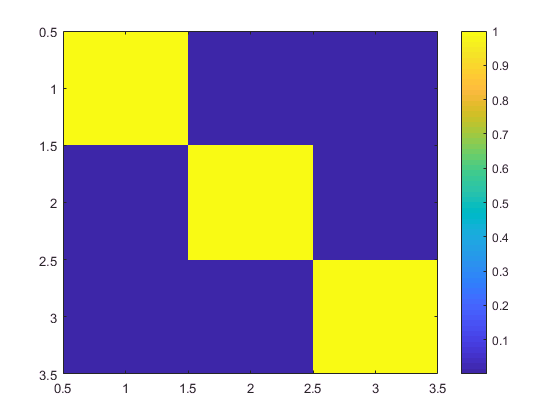

% demonstrate that V is made up of orthonormal vectors
figure;  
imagesc(V * V.'); 
colorbar

**Summarise what we have so far**

So we finally have our PRINCIPAL moments of inertia $({^PI})$ AND we know how the PRINCIPAL axes are orientated relative to the B-frame $({V^{-1}} \equiv {^PR_B} )$ .. AND we've checked for a RH frame:

% so let's summarise what we've got
Ip_mat

Ip_mat =           55.9036216319413                         0                         0
                         0          193.152275905814                         0
                         0                         0          227.034102462245


V

V =         -0.797353030582144        -0.111887356741905        -0.593050894968366
        -0.458290582862403         0.751631273019369          0.47436291073283
         0.392680386932056         0.650024344790711         -0.65059239535849


## **Next step:   Let's define our passive Rotation matrix **$({^PR_B})$

Recall some of the formulaes mentioned earlier:

- 
$${^Pu} = {^PR_B} \times {^Bu}$$


- 
$$ {^PR_B}  = {V^{-1}} = V^T$$


pRb = V.'

pRb =         -0.797353030582144        -0.458290582862403         0.392680386932056
        -0.111887356741905         0.751631273019369         0.650024344790711
        -0.593050894968366          0.47436291073283         -0.65059239535849


## Let's have a closer look at the passive Rotation matrix $({^PR_B})$

First I'd like to plot the unit vectors of our original B-frame:

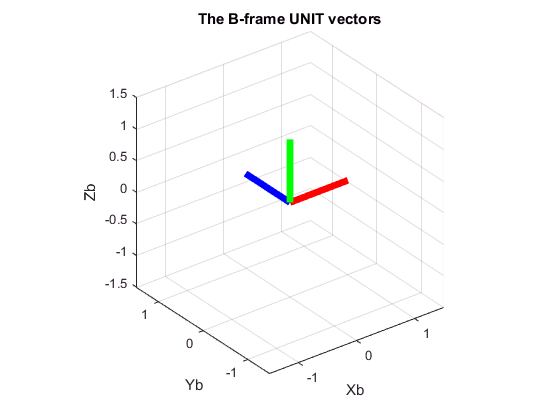

figure
   % Plot the B-frame UNIT vectors 
   bx_u = [1;0;0];
   by_u = [0;1;0];
   bz_u = [0;0;1];
            
   bh_plot_triad( gca, bx_u, by_u, bz_u );  view(3);
      title('The B-frame UNIT vectors')

What I'd now like to do is to plot the P-frame unit vectors, but I want to draw them in the B-frame.  To compute the components of the P-frame expressed in terms of the B-frame we can just use our passive rotation matrices.  Recall what our passive rotation $({^PR_B})$matrix does:  


$${^Pu} = {^PR_B} \times {^Bu} $$


So to transform our P-frame unit vectors into their corresponding components in the B-frame we use the following PASSIVE rotation matrix:


$${^Bu} = {(^PR_B)^T} \times {^Pu}$$


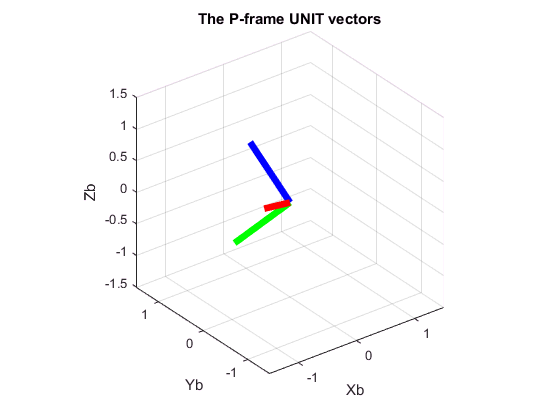

figure
   % express the unit vectors of P into their components in the B-frame 
   b_xi_p = pRb.' * [1;0;0];
   b_yi_p = pRb.' * [0;1;0];
   b_zi_p = pRb.' * [0;0;1];
    
   bh_plot_triad( gca, b_xi_p, b_yi_p , b_zi_p );   view(3);
      title('The P-frame UNIT vectors')

## How about some more clarity ?

The Inertia matrix ${^BI}$ that we've just been looking at, was actually produced from a "cloud" that we've  filled with tetrahedrons.  We manully computed the system Inertia matrix from this "discretised" volume.  Here's what the cloud looks like ... with the original BODY axes and **PRINCIPAL** axes superimposed.  It looks alot better when you interactively rotate the plots in MATLAB.

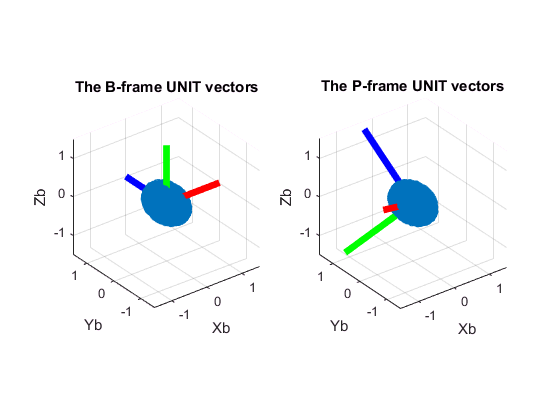

SRC_DATA = load('bh_saved_ellip_cloud.mat');

figure;
hax(1) = subplot(1,2,1);
        scatter3(SRC_DATA.new_x_col, SRC_DATA.new_y_col, SRC_DATA.new_z_col); 
            % Plot the B-frame DOUBLE unit vectors 
            bx_u = [2;0;0];
            by_u = [0;2;0];
            bz_u = [0;0;2];
            hold('on');      
        bh_plot_triad( gca, bx_u, by_u, bz_u );   view(3); %view(-134,-34)
        title('The B-frame UNIT vectors')
hax(2) = subplot(1,2,2);
        scatter3(SRC_DATA.new_x_col, SRC_DATA.new_y_col, SRC_DATA.new_z_col);  
            % express the DOUBLE unit vectors of P into their components in the B-frame 
            b_xi_p = pRb.' * [2;0;0];
            b_yi_p = pRb.' * [0;2;0];
            b_zi_p = pRb.' * [0;0;2];
            hold('on');
        bh_plot_triad( gca, b_xi_p, b_yi_p, b_zi_p );   view(3); %view(-134,-34)
            title('The P-frame UNIT vectors')

% to see the axes rotate together you'll need to 
% "evaluate selection in command window"            
hlink = linkprop([hax(1),hax(2)],{'CameraPosition','CameraUpVector'});

# Who new a story about **potatoes** could be so much **fun** ?

# **Tutorial questions:**

## **QUESTION 1.)  **

Consider the following 3 bladed propeller:

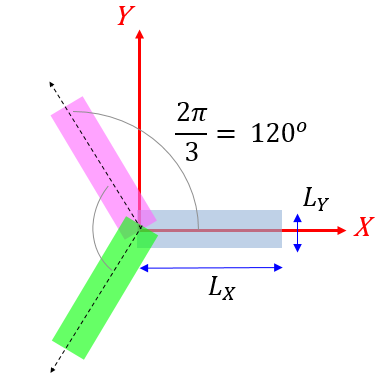 where each blade can be represented by a thin rectangular plate.

- Compute the inertia of the system about the X-Y frame shown above - what do you conclude ?

- Calculate the Principle moments of inertia and their orientation relative to the X-Y frame shown above - do these results support your earlier findings ?

## **QUESTION 2.)  **

Consider the following 3 bladed propeller that hsa been placed in an "arbitrary" pose

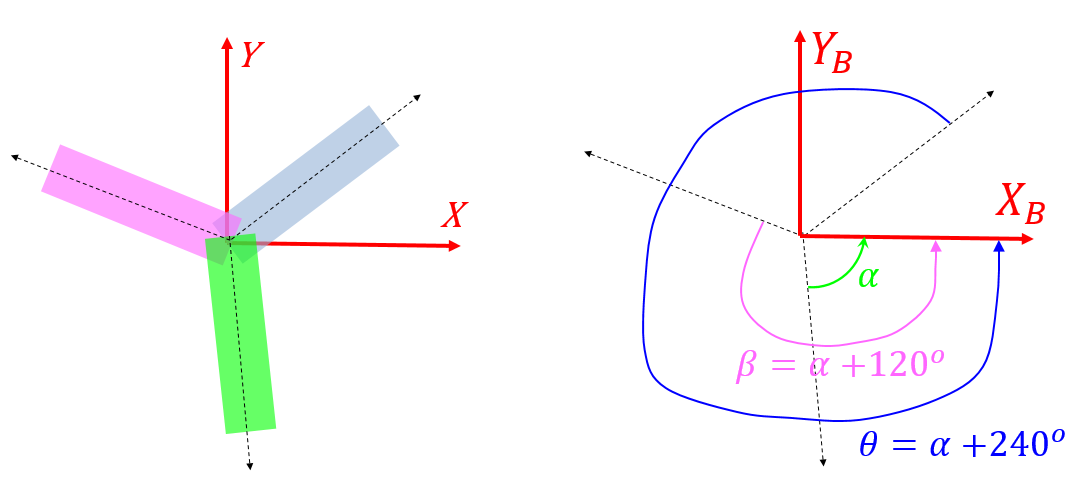

- Compute the inertia of the system about the X-Y frame shown above - what do you conclude ?

- Calculate the Principle moments of inertia and their orientation relative to the X-Y frame shown above - do these results support your earlier findings ?